# Laboratory1 : Welding of a Spherical Manipulator

## Objective:

    to solve and to create the Pick and Place Program Mechanical Manipulator (In this case, Spherical Manipulator)

## Algorithm:

    1. Identify the Link Length

    2. Create a Denavit Hartenberg Paramteric Table

    3. Plug-in the Matrix of the following Manipulator

    4. Matrix Multiply the Transformation Matrices.

    5. Once done, we can get the Jacobian matrix by jacob0()

    6. The following Coordinates will be defined via the ikine() method

    7. Use step 2 to Plot the Trajectories

## Conventions Used:

    a_<number> - Constant Link Length

    theta = Joint Offset

    alpha = Link Twist

    r = Link Length

    d = Link Offset

### Display the Lengths

% Clear All Defined Variables

clear all;
clc;

disp("Spherical Manipulator")

Spherical Manipulator



syms a1 a2 a3

% Link Lengths a1 to a3

a1 = 20; %20m
a2 = 10; %15m
a3 = 10; %15m

### Defining the DH Parameters

In, Python, we tend to compute the Matrix of it based on the specific angles given. Since in Reality, Mechanical Manipulators tend not to work on this way. We must program a mathematical model of machanical manipulators to visualize the movement itself.

% Take note of theta, alpha, r/a, and d
H_01 = Revolute('alpha', pi/2, 'd', a1)

 
H_01 = 
Revolute(std): theta=q, d=20, a=0, alpha=1.5708, offset=0


H_12 = Revolute('alpha', pi/2, 'offset', pi/2)

 
H_12 = 
Revolute(std): theta=q, d=0, a=0, alpha=1.5708, offset=1.5708


H_23 = Prismatic('offset', a2 + a3)

 
H_23 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=20



%Defining the Joint Limits (IRL it has following limits of course)

H_01.qlim = pi/180 * [-90, 90];
H_12.qlim = pi/180 * [-90, 90];
H_23.qlim = [0, 50];

### Combining the DH Parameters into a `SerialLink` object

Once created the following DH Parameters, we can connect using a SerialLink object. This displays the DH Parametric Table we've discussed in Robotics 1

Spherical = SerialLink([H_01, H_12,H_23], 'name', 'Spherical Manipulator')

 
Spherical = 
 
Spherical Manipulator:: 3 axis, RRP, stdDH, slowRNE              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         20|          0|     1.5708|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|          0|         q3|          0|          0|         20|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Plotting and Teaching the Robot

Once done, we are about to plot the robot in the origin, and teach the robot (Have Sliders to know the position of the end effector based on the jont angles)

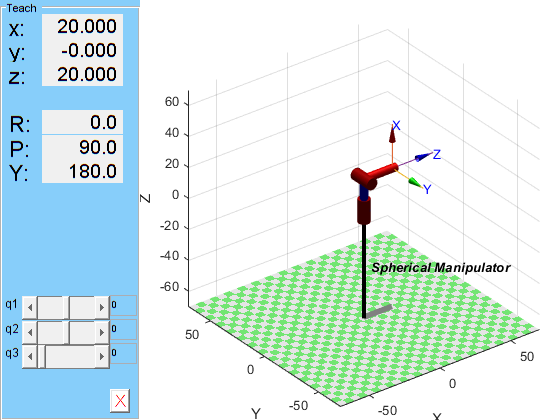

origin = [0 0 0];
workspace = [-25,25,-25,25,-10,25];
Spherical.plot(origin);
Spherical.teach();

#### Jacobian Matrix Generation

For the Generation of Jacobian Matrix, we can able to generate using jacob0() command

J_TestValue1 = jacob0(Spherical, [-pi/2,-pi/2,0])

J_TestValue1 =     0.0000    0.0000   -0.0000
   -0.0000  -20.0000   -0.0000
    0.0000         0   -1.0000
         0   -1.0000         0
         0   -0.0000         0
    1.0000    0.0000         0


J_TestValue2 = jacob0(Spherical, [-pi/4,-pi/4,12.5])

J_TestValue2 =    16.2500   16.2500    0.5000
   16.2500  -16.2500   -0.5000
    0.0000   22.9810   -0.7071
    0.0000   -0.7071         0
    0.0000   -0.7071         0
    1.0000    0.0000         0


J_TestValue3 = jacob0(Spherical, [0,0,25])

J_TestValue3 =     0.0000    0.0000    1.0000
   45.0000    0.0000   -0.0000
         0   45.0000   -0.0000
   -0.0000         0         0
         0   -1.0000         0
    1.0000    0.0000         0


J_TestValue4 = jacob0(Spherical, [pi/4,pi/4,37.5])

J_TestValue4 =   -28.7500  -28.7500    0.5000
   28.7500  -28.7500    0.5000
    0.0000   40.6586    0.7071
   -0.0000    0.7071         0
   -0.0000   -0.7071         0
    1.0000    0.0000         0


J_TestValue5 = jacob0(Spherical, [pi/2,pi/2,50])

J_TestValue5 =    -0.0000   -0.0000    0.0000
    0.0000  -70.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000         0
         0   -0.0000         0
    1.0000    0.0000         0


#### **Defining the following Coordinates of the Box and Conveyor Belt**

We Define now the coordinates of the conveyor belt and box via the ikine() command

original_pose = Spherical.ikine(SE3(30, 0, 20),'mask', [1, 1, 1, 0, 0, 0])

original_pose =     0.0000    0.0000   10.0000


point1 = Spherical.ikine(SE3(31, 5, 10),'mask', [1, 1, 1, 0, 0, 0])

point1 =     0.1599   -0.3083   12.9545


point2 = Spherical.ikine(SE3(33, 5, 10), 'mask', [1, 1, 1, 0, 0, 0])

point2 =     0.1504   -0.2911   14.8425


point3 = Spherical.ikine(SE3(33, -5, 10),'mask', [1, 1, 1, 0, 0, 0])

point3 =    -0.1504   -0.2911   14.8425


point4 = Spherical.ikine(SE3(31, -5, 10), 'mask', [1, 1, 1, 0, 0, 0])

point4 =    -0.1599   -0.3083   12.9545


#### Next, we define the Trajectories of the following Pick and Place Robot

traj1 = jtraj(original_pose, point1, 20)

traj1 =     0.0000    0.0000   10.0000
    0.0002   -0.0004   10.0040
    0.0016   -0.0031   10.0292
    0.0049   -0.0094   10.0905
    0.0106   -0.0204   10.1960
    0.0189   -0.0363   10.3483
    0.0295   -0.0569   10.5454
    0.0423   -0.0815   10.7813
    0.0567   -0.1093   11.0471
    0.0721   -0.1390   11.3317


traj2 = jtraj(point1, point2, 20)

traj2 =     0.1599   -0.3083   12.9545
    0.1599   -0.3083   12.9571
    0.1598   -0.3081   12.9732
    0.1596   -0.3078   13.0123
    0.1593   -0.3072   13.0797
    0.1588   -0.3063   13.1771
    0.1582   -0.3051   13.3030
    0.1574   -0.3038   13.4538
    0.1565   -0.3022   13.6236
    0.1556   -0.3006   13.8055


traj3= jtraj(point2, point3, 20)

traj3 =     0.1504   -0.2911   14.8425
    0.1500   -0.2911   14.8425
    0.1474   -0.2911   14.8425
    0.1412   -0.2911   14.8425
    0.1304   -0.2911   14.8425
    0.1149   -0.2911   14.8425
    0.0949   -0.2911   14.8425
    0.0708   -0.2911   14.8425
    0.0438   -0.2911   14.8425
    0.0148   -0.2911   14.8425


traj4 = jtraj(point3, point4, 20)

traj4 =    -0.1504   -0.2911   14.8425
   -0.1504   -0.2911   14.8400
   -0.1505   -0.2913   14.8238
   -0.1507   -0.2916   14.7847
   -0.1510   -0.2922   14.7173
   -0.1515   -0.2931   14.6200
   -0.1521   -0.2943   14.4940
   -0.1529   -0.2957   14.3432
   -0.1538   -0.2972   14.1734
   -0.1547   -0.2989   13.9915


traj5 = jtraj(point4, point1, 20)

traj5 =    -0.1599   -0.3083   12.9545
   -0.1595   -0.3083   12.9545
   -0.1567   -0.3083   12.9545
   -0.1501   -0.3083   12.9545
   -0.1387   -0.3083   12.9545
   -0.1222   -0.3083   12.9545
   -0.1009   -0.3083   12.9545
   -0.0753   -0.3083   12.9545
   -0.0466   -0.3083   12.9545
   -0.0158   -0.3083   12.9545


traj6 = jtraj(point1, original_pose, 20)

traj6 =     0.1599   -0.3083   12.9545
    0.1597   -0.3079   12.9505
    0.1583   -0.3053   12.9253
    0.1550   -0.2989   12.8640
    0.1493   -0.2879   12.7586
    0.1411   -0.2720   12.6062
    0.1304   -0.2514   12.4091
    0.1176   -0.2268   12.1732
    0.1032   -0.1990   11.9074
    0.0878   -0.1693   11.6228
